clear; clc;

dataNum = 5;

% 设置导入选项并导入数据
opts = delimitedTextImportOptions("NumVariables", dataNum + 1);

% 指定范围和分隔符
opts.DataLines = [dataNum + 4, Inf];
opts.Delimiter = ",";

% 指定列名称和类型
% 旧：时间 光栅尺X1 电流X1 扭矩X1 电流X13 扭矩X13
% 新：时间 光栅尺X1 光栅尺X13 电流X1 电流X13 扭矩X1 扭矩X13
% opts.VariableNames = ["time", "f1\s1", "f2\s2", "f3\s3", "f4\s4", "f5\s5", "f6\s6"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% 指定文件级属性
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.VariableNamingRule = 'preserve';

% 导入数据
siemensData = readmatrix("D:\Research\experiments\Siemens results\20240527 Siemens\X_XIA_A2_J5_1__ZHONG.csv", opts);

% 转换为输出类型
% siemensData = table2array(siemensData);

% 清除临时变量
clear opts


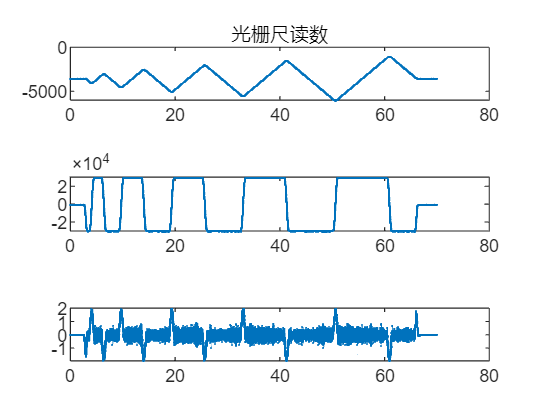


fig1 = figure('Name','光栅尺读数');
tiledlayout(3,1);
nexttile;
plot(siemensData(:,1),siemensData(:,2),'-o','MarkerSize',0.5);
hold on;
% nexttile;
title('光栅尺读数');

% fig2 = figure('Name','光栅尺速度');
nexttile;
simensVelo1 = 60*(siemensData(2:end,2) - siemensData(1:end - 1,2))./(siemensData(2:end,1) - siemensData(1:end - 1,1));
plot(siemensData(2:end,1),simensVelo1,'-o','MarkerSize',0.5);
hold on;
% simensVelo13 = (siemensData(2:end,2) - siemensData(1:end - 1,2))./60000./(siemensData(2:end,1) - siemensData(1:end - 1,1));
% plot(siemensData(2:end,1),simensVelo13,'-o','MarkerSize',0.5);
% title('光栅尺速度');

% fig3 = figure('Name','光栅尺加速度');
nexttile;
simensAccel1 = (simensVelo1(2:end) - simensVelo1(1:end - 1))./60000./(siemensData(3:end,1) - siemensData(2:end - 1,1));
plot(siemensData(3:end,1),simensAccel1,'-o','MarkerSize',0.5);
hold on;

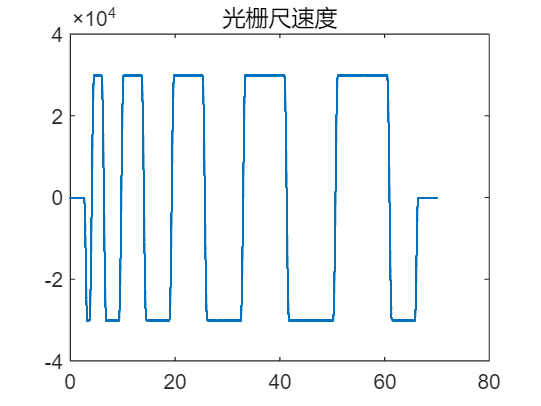

% simensAccel13 = (simensVelo13(2:end) - simensVelo13(1:end - 1))./60000./(siemensData(2:end,1) - siemensData(1:end - 1,1));
% plot(siemensData(2:end,1),simensAccel13,'-o','MarkerSize',0.5);
% title('光栅尺加速度');

fig2 = figure('Name','光栅尺速度');
plot(siemensData(2:end,1),simensVelo1,'-o','MarkerSize',0.5);
title('光栅尺速度');

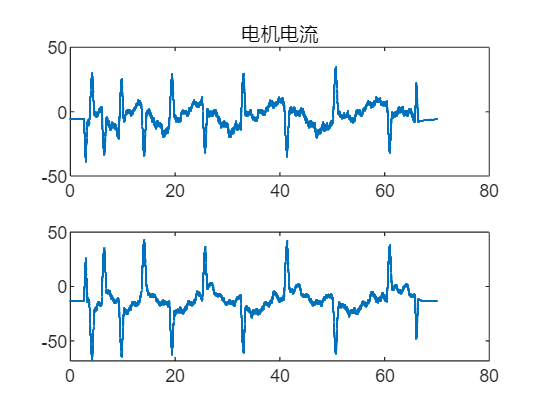


fig4 = figure('Name','电机电流');
tiledlayout(2,1);
nexttile
plot(siemensData(:,1),siemensData(:,3),'-o','MarkerSize',0.5);
title('电机电流');
nexttile;
plot(siemensData(:,1),siemensData(:,5),'-o','MarkerSize',0.5);

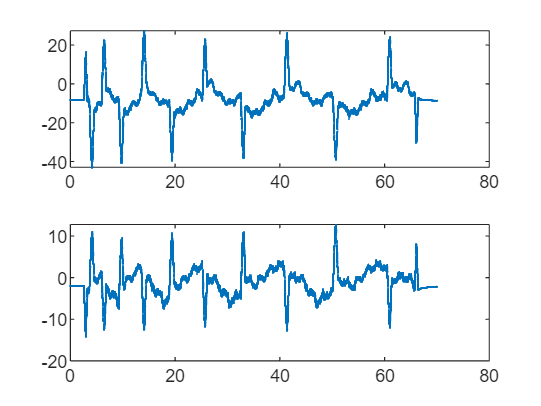


fig5 = figure('Name','电机扭矩');
title('电机扭矩');
tiledlayout(2,1);
nexttile
plot(siemensData(:,1),siemensData(:,4),'-o','MarkerSize',0.5);
nexttile;
plot(siemensData(:,1),siemensData(:,6),'-o','MarkerSize',0.5);